clear
data = load('EteV35Nu10.txt');
heure  = data(:,1)';
D = data(:,2)';
Peol = data(:,3)';
Ppv = data(:,4)';
Prix = data(:,5);
QH2_min = 100;
N = length(heure);
Celec = 1;
Pelec_min = 5;
Pelec_max = 30;
relec = 0.6;

fobj = @(elec) (elec(1,1:N) + D - Ppv - Peol)*Prix + Celec*sum(elec(1,1:N));  
lb = zeros(1,2*N);
ub = [Pelec_max*ones(1,N) , ones(1,N)];
A = [eye(N) , -Pelec_max*eye(N)
     -eye(N) , Pelec_min*eye(N)
     -ones(1,N)*relec , zeros(1,N)];
b = [zeros(2*N,1) ; -QH2_min];
Aeq = [];
beq = [];
nonlcon = [];


Intcon = (N+1):2*N;
pop = 200;
options = optimoptions('ga');
options.PopulationSize = pop;
options.EliteCount = 0.3*pop;
On = randi(2,pop,N) - 1;
P = (5 + rand(pop,N)*25).*On;
Init = [P , On];
options.InitialPopulationMatrix = Init;
[x,fval,exitflag,output,population,scores] = ga(fobj,2*N,A,b,Aeq,beq,lb,ub,nonlcon,Intcon,options);

Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.


disp(sum(x(1,1:N))*relec)

   99.9991



x0 = zeros(1,2*N);
x0(1,N+1:2*N) = randi(2,1,N) - 1;
x0(1,1:N)= (Pelec_min + rand(1,N)*(Pelec_max - Pelec_min)).*x0(1,N+1:2*N);
probleme = createOptimProblem('fmincon','x0',x0,'objective',fobj,'lb',lb,'ub',ub,'Aineq',A,'bineq',b);
[sol,val]=run(GlobalSearch,probleme);

GlobalSearch stopped because it analyzed all the trial points.

16 out of 56 local solver runs converged with a positive local solver exit flag.


disp(sum(sol(1:N))*relec)

  100.0000



clear
data = load('AutonV50Nu40.txt');
heure  = data(:,1)';
D = data(:,2)';
Peol = data(:,3)';
Ppv = data(:,4)';
Prix = data(:,5);
QH2_max = 20;
QH2_prod_max = 20;
N = length(heure);
Cpac = -4;
Celec = 1;
Ppac_max = 15;
Pelec_max = 30;
rpac = 0.8;
relec = 0.6;

fobj = @(P) [ sum(P(1,N+1:2*N))/rpac - sum(P(1,1:N))*relec , (P(1,1:N) + D - Ppv - Peol - P(1,N+1:2*N))*Prix + Celec*sum(P(1,1:N)) + Cpac*sum(P(1,N+1:2*N))];
lb = zeros(1,2*N);
ub = [Pelec_max*ones(1,N) , Ppac_max*ones(1,N)];
A = [-ones(1,N)*relec , ones(1,N)/rpac
     ones(1,N)*relec , zeros(1,N)];
b = [QH2_max ; QH2_prod_max];
Aeq = [];
beq = [];
nonlcon = [];
n_points = 10;
n_pop = 100;

options = optimoptions('gamultiobj');
options.PopulationSize = n_pop;
options.ParetoFraction = 0.35;
[x_ga,fval_ga,exitflag_ga,output_ga,population_ga,scores_ga] = gamultiobj(fobj,2*N,A,b,Aeq,beq,lb,ub,nonlcon,options);

Optimization terminated: average change in the spread of Pareto solutions less than options.FunctionTolerance.


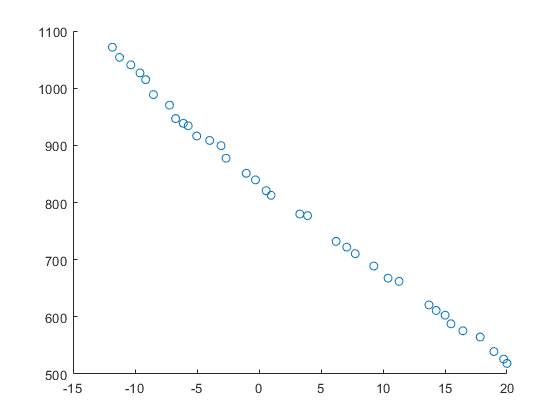

figure
scatter(fval_ga(:,1),fval_ga(:,2))

options = optimoptions('paretosearch');
options.ParetoSetSize = n_points;
options.MinPollFraction = 1;
On = randi(2,n_points,N) - 1;
Init = [On.*rand(n_points,N)*QH2_prod_max/relec/24 , (1 - On).*rand(n_points,N)*QH2_max*rpac/24];
options.InitialPoints = Init;
[x_ps,fval_ps,exitflag_ps,output_ps,residuals_ps] = paretosearch(fobj,2*N,A,b,Aeq,beq,lb,ub,nonlcon,options);


Pareto set found that satisfies the constraints. 

Optimization completed because the relative change in the volume of the Pareto set 
is less than 'options.ParetoSetChangeTolerance' and constraints are satisfied to within 
'options.ConstraintTolerance'.



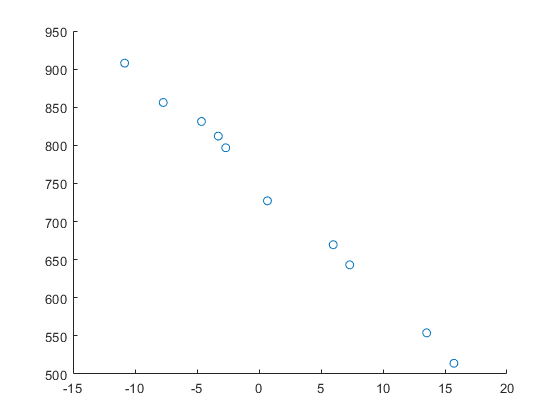

figure
scatter(fval_ps(:,1),fval_ps(:,2))